Declaration of variables

clc;
clear;

Road_length = 1000;
car_number   = 5

car_number = 5

acceleration =3.5

acceleration = 3.5000

deceleration =-5.5

deceleration = -5.5000

%initial speed
u = 5

u = 5

%time limitis
time =50

time = 50

%limit speed
lim = 15

lim = 15

%initial position of car
J = 1:car_number

J =      1     2     3     4     5


A = rand(1,car_number).*Road_length

A =   173.3886  390.9378  831.3797  803.3644   60.4712


x(J,1)= sort(A)

x =    60.4712
  173.3886
  390.9378
  803.3644
  831.3797


v(J,1)=randi([0,car_number],car_number,1)

v =      2
     3
     2
     3
     3


%minimum distance between cars
x0 = Road_length/car_number

x0 = 200

num = car_number-1

num = 4

delT=0.1

delT = 0.1000

k = time / delT

k = 500

%
average(1) =0

average = 0

initialize road

for T=2:k
    for J=1:car_number
        if J == car_number
            dis(J,T) = x(1,T-1)-x(J,T-1);
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length + dis(J,T);
        end
        if dis(J,T) > x0
           v(J,T)=v(J,T-1) + acceleration;
        elseif dis(J,T) <= deceleration 
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        x(J,T)=x(J,T-1)+v(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
end
x(J,T)=x(J,T)

x =    60.4712   60.4712   60.4712   60.4712   60.4712   60.4712   60.4712   60.4712   63.9712   70.9712   81.4712   95.4712  110.4712  125.4712  140.4712  155.4712  170.4712  185.4712  200.4712  215.4712  230.4712  245.4712  254.9712  258.9712  258.9712  258.9712  258.9712  258.9712  258.9712  258.9712  258.9712  258.9712  262.4712  269.4712  279.9712  293.9712  308.9712  323.9712  338.9712  353.9712  363.4712  367.4712  367.4712  367.4712  367.4712  367.4712  367.4712  367.4712  367.4712  367.4712
  173.3886  179.8886  189.8886  203.3886  218.3886  233.3886  248.3886  263.3886  278.3886  293.3886  308.3886  323.3886  338.3886  353.3886  368.3886  383.3886  398.3886  413.3886  428.3886  437.8886  441.8886  441.8886  441.8886  441.8886  441.8886  441.8886  441.8886  441.8886  441.8886  445.3886  452.3886  462.8886  476.8886  491.8886  506.8886  521.8886  536.8886  546.3886  550.3886  550.3886  550.3886  550.3886  550.3886  550.3886  550.3886  550.3886  550.3886  553.8886  560.8886  571

v(J,T)=v(J,T)

v =     2.0000         0         0         0         0         0         0         0    3.5000    7.0000   10.5000   14.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000    9.5000    4.0000         0         0         0         0         0         0         0         0    3.5000    7.0000   10.5000   14.0000   15.0000   15.0000   15.0000   15.0000    9.5000    4.0000         0         0         0         0         0         0         0         0
    3.0000    6.5000   10.0000   13.5000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000    9.5000    4.0000         0         0         0         0         0         0         0         0    3.5000    7.0000   10.5000   14.0000   15.0000   15.0000   15.0000   15.0000    9.5000    4.0000         0         0         0         0         0         0         0         0    3.5000    7.0000   10

average(T) = average(T)

average =          0    3.7000    5.8000    7.9000    7.6000    6.5000    6.0000    6.0000    6.7000    7.4000    8.1000    9.5000   10.4000   11.1000   11.8000   12.0000   12.0000   10.9000    9.8000    7.9000    6.8000    6.0000    5.6000    5.2000    5.1000    5.8000    5.6000    5.2000    5.1000    6.5000    6.3000    5.9000    6.5000    7.4000    7.0000    6.6000    6.7000    6.3000    5.9000    5.8000    5.6000    5.2000    5.1000    5.8000    5.6000    5.2000    5.1000    6.5000    6.3000    5.9000


k_1 = floor(k/3);
d_av = average(1,(k_1):k)

d_av =     5.8000    5.6000    5.2000    5.1000    5.8000    5.6000    5.2000    5.1000    6.5000    6.3000    5.9000    6.5000    7.4000    7.0000    6.6000    6.7000    6.3000    5.9000    5.8000    5.6000    5.2000    5.1000    5.8000    5.6000    5.2000    5.1000    6.5000    6.3000    5.9000    6.5000    7.4000    7.0000    6.6000    6.7000    6.3000    5.9000    5.8000    5.6000    5.2000    5.1000    5.8000    5.6000    5.2000    5.1000    6.5000    6.3000    5.9000    6.5000    7.4000    7.0000


av = mean(d_av)

av = 6.0152

Plot

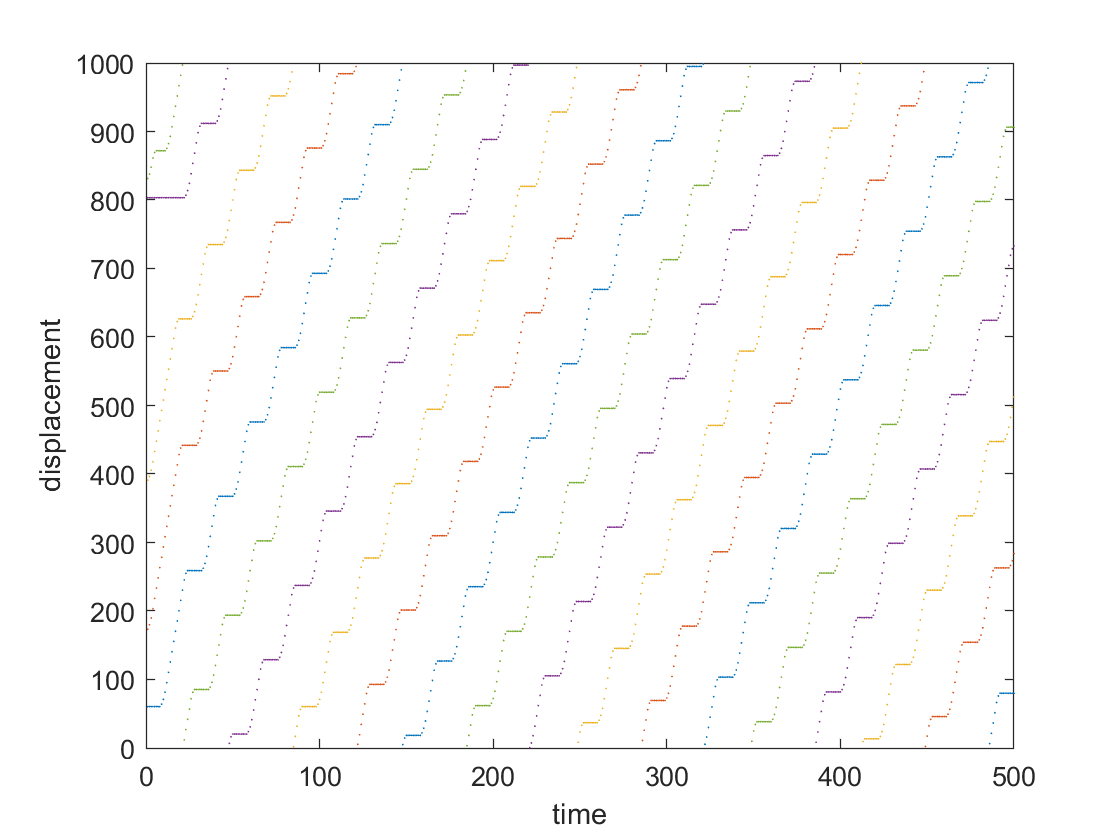

plot(x(1,:),".","MarkerSize",2);
hold on
for b = 2: car_number
    plot(x(b,:),".","MarkerSize",2)
end
xlabel('time')
ylabel('displacement')
hold off;

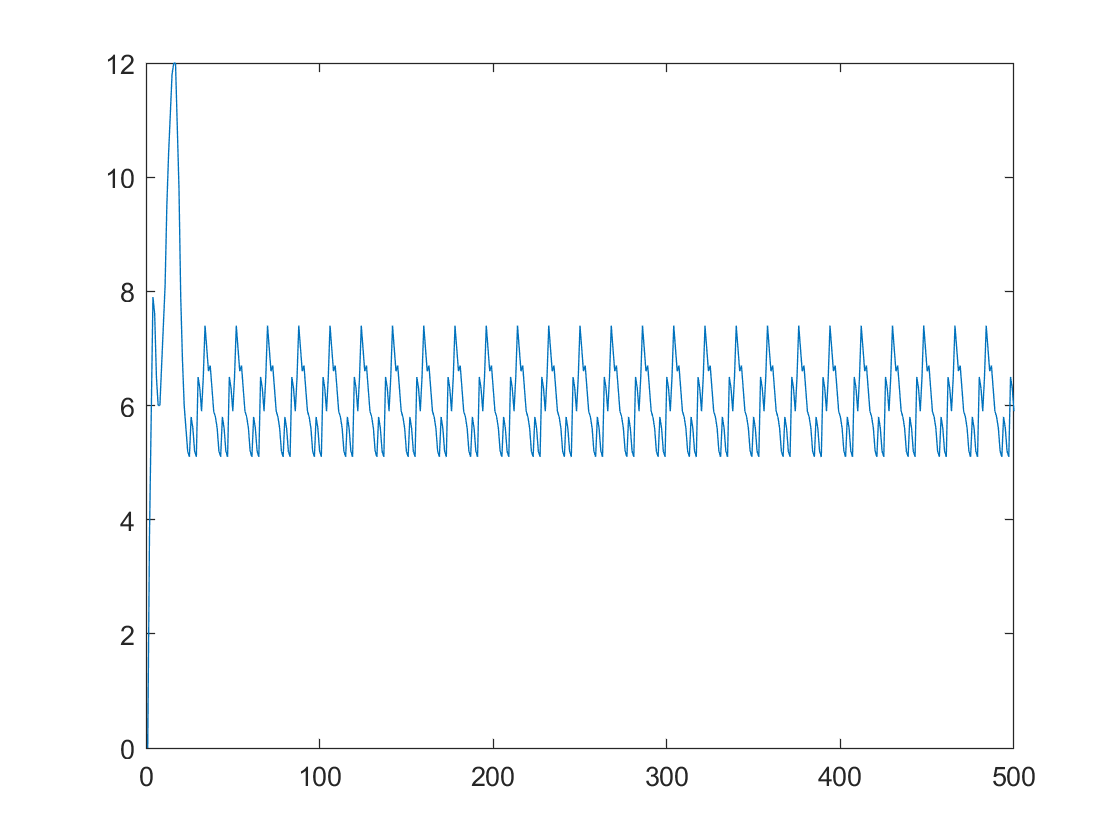

plot(average)